clear; close all; clc; % initializes environment

# 任意の方向の分散と分散共分散行列の導入

## 本章の目的

前章では，pca()関数の３つの出力引数（「主成分係数」「主成分スコア」「主成分分散」）の意味と照らし合わせながら，PCAによる次元圧縮を３つのステップで概説しました．要約すると，

- データの分散をもっともよく説明する軸（主軸）を見つける（「主成分係数」の各列が主軸の方向を示す）

- 主軸が座用軸になるようにデータを回転させる（回転後の座標が「主成分スコア」に相当）

- 分散を多く含む主軸を残して，残りの次元を削減する（各主軸で表現される分散「主成分分散」が基準となる）

となります．こうすることで，データがもつ分散をできる限り損なわずに次元を削減することが可能になります．ここで肝心となるのは，少ない数の主軸にデータの分散をいかに集中させるかということです．言い換えると，少ない数の主軸にできるだけ多くの分散が表現されるような軸（方向）を見つけることが重要な課題となります．本章では，「データの分散をもっともよく説明する軸」という点について，定式化とグラフ化を通してもう少し詳しく掘り下げて解説していきます．

まず，複数の方向における分散を求め，その方向によって求められる分散の値が異なることを確認します．前章では，主軸方向の分散と座標軸方向の分散をそれぞれ計算し比較することで，分散を求める方向によってその値が変わることを説明しました．本章ではさらに，複数の方向における分散を求め，分散が方向によって異なることを確認します．

つぎに，任意の方向における分散を定式化します．「データの分散が最大限に含まれる方向（主軸）を探す」という課題を解くうえで基本的な考え方は，関数の最大値を求める方法になぞらえることができます．つまり，

- 任意の方向における分散を定式化する

- 分散が最大になるときの方向（主軸）を見つける

という二つのステップで考えることができます．本章では，一つ目の定式化を行います．また，その過程で，「分散共分散行列」を定義します．「分散共分散行列」は固有値分解を利用したPCAの計算方法（アルゴリズム）の核となる行列です．その意味と性質について解説します．

最後に，任意の単位ベクトルが示す方向における分散を，単位ベクトルの関数としてとらえて，立体的なグラフとして視覚的に解説します．このイメージは本稿で解説する「分散共分散行列の固有値分解によるPCA」の核となるイメージです．

## データの準備

引き続き，「米国３２９都市における生活満足度」のデータセットを用います．前章と同様，「健康」と「芸術」に関する指標を用いて，変数とする二変量データとして解説していきます．また，説明を簡単にするために，平均値が０，標準偏差が１になるように正規化しておきます．

load cities.mat;
scores_health_norm = normalize(ratings(:, 3)); % extracts scores on healt (the 3rd  column) and normalizes it
scores_arts_norm = normalize(ratings(:, 7)); % extracts scores on arts (the 7th column) and normalizes it

数式での表記と一致させるために，「健康」および「芸術」に関する正規化された評価値を**行**にもつデータ行列$X$を定義します．

X = [scores_health_norm scores_arts_norm]'

X =    -0.9459    0.4689   -0.5660    0.2445    0.6653   -0.5441   -0.5630   -0.2201   -0.7515   -0.5152    0.8367   -0.5830   -0.6039   -0.3646    1.3183   -0.5860   -0.3517    0.0182   -0.5790    2.0032   -0.5471    0.6104    0.0172   -0.4025   -0.7634    2.3691   -0.4045   -0.8412   -0.2849   -0.5680   -0.3238   -0.9429   -0.6139    1.4708   -0.7046   -0.7425   -0.1782    0.5047   -0.3806   -0.4534   -0.3696   -0.7305    4.1029   -0.2231   -0.8502   -0.7455   -0.8731    1.3602   -0.2101   -0.2689
   -0.4642    0.5198   -0.6277    0.3240    0.2898   -0.6068   -0.1762   -0.3584   -0.6236   -0.4127    0.5345   -0.1734   -0.5861   -0.6423    0.9496   -0.6210   -0.4276   -0.3791    0.0851    0.9496   -0.5450   -0.4532    0.1521    0.4748   -0.4155    1.4297   -0.2490    0.2340   -0.6025   -0.2921   -0.4021   -0.3983   -0.6617    1.3255   -0.5111   -0.5325   -0.3343    0.1739   -0.4179   -0.2152   -0.3621   -0.1650    3.8539    0.1103   -0.6456   -0.3543   -0.5964    1.1238   -0.5680   -0

これまでと異なり，各行が変数，各列が観測に対応します．以降では，データ行列$X$の$i$番目の観測を$x^{\left(i\right)} =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1^{\left(\mathrm{i}\right)} \\
{\mathrm{x}}_2^{\left(\mathrm{i}\right)} 
\end{array}\right\rbrack$と表すことにします．ここで，${\mathrm{x}}_1^{\left(\mathrm{i}\right)}$および${\mathrm{x}}_2^{\left(\mathrm{i}\right)}$はそれぞれデータ行列$X$の$i$番目の観測における一番目の変数（「健康」）と二番目の変数（「芸術」）の値です．

## 任意の方向における分散

ここでは，任意の方向における分散を定式化し，方向によって求められる分散の値が異なることを確認します．分散の定式化に先立って，正射影ベクトルとその長さおよび平均，分散を解説します．この分散こそが今回求めるべき分散です．最後に，いくつかの異なる方向での分散を求めて，分散を求める方向とその値の関係を視覚的に理解できるようにします．

### 正射影ベクトル

まずは二変量データを使って正射影ベクトルの図形的なイメージを具体的に見ていきましょう．下の図は二変量データ$X$の散布図です．

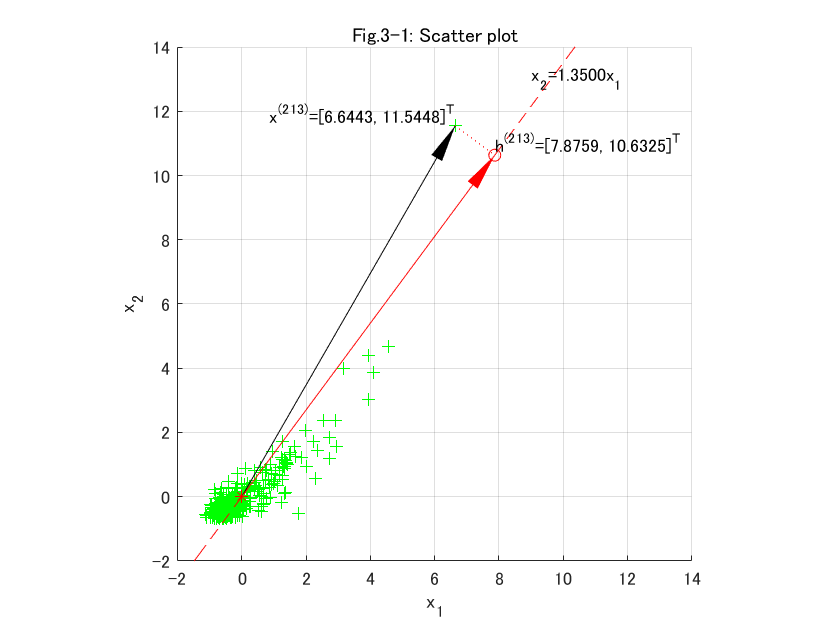

figure('Name','Fig.3-1: Scatter plot');
% plot the bivariate data
scatter(X(1,:),X(2,:),'g+'); grid on; hold on;
title('Fig.3-1: Scatter plot'); xlabel('x_1'); ylabel('x_2');
axis([-2 14 -2 14]); axis square;
% plot origin
plot(0,0,'r*');
x1= linspace(-2,14,100);
% plot y=1.35x
a = [1 1.35]'; % slope: [dx dy]
x2 = a(2)/a(1)*x1;
plot(x1,x2,'r--');
str_text = sprintf('x_2=%0.4fx_1',a(2)/a(1));
text(9,13,str_text);
% plot a sample point, x(213)
[~, x1_max_ind] = max(X(1,:)); % find the index of the maximum of the x1
str_H = sprintf('x^{(%d)}=[%0.4f, %0.4f]^T',x1_max_ind,X(1,x1_max_ind),X(2,x1_max_ind));
text(X(1,x1_max_ind),X(2,x1_max_ind),str_H,'VerticalAlignment','bottom','HorizontalAlignment','right');
% plot a perpendicular foot, h(123)
A = [-a(2) a(1); a(1) a(2)]; % Two equations for the x2=1.35x1 and the its orthogonal line.
B = [0; dot(a,X(:,x1_max_ind))];
c = linsolve(A,B); % solving the 2 equations.
plot(c(1),c(2),'ro');
str_Hprime = sprintf('h^{(%d)}=[%0.4f, %0.4f]^T',x1_max_ind,c(1),c(2));
text(c(1),c(2),str_Hprime,'HorizontalAlignment','right','VerticalAlignment','bottom','HorizontalAlignment','left');
arrow3([X(1,x1_max_ind),X(2,x1_max_ind)],[c(1),c(2)],'r:',0);
arrow3([0 0],[X(1,x1_max_ind) X(2,x1_max_ind)],'k');
arrow3([0 0],[c(1) c(2)],'r');

赤色の破線は${\mathrm{x}}_2 =1\ldotp 35{\mathrm{x}}_1$で表される直線です．黒色の矢印は213番目のデータ点$x^{\left(213\right)}$を示します．そこから赤色破線にむけて垂線が引かれています（赤点線）．$h^{\left(213\right)}$はこのときの垂線の足（直線と垂線の交点）です．赤色の矢印は原点から垂線の足$h^{\left(213\right)}$までの座標ベクトルとして明示したものです．このとき，ベクトル$h^{\left(213\right)}$はベクトル$x^{\left(9\right)}$を直線${\mathrm{x}}_2 =1\ldotp 35{\mathrm{x}}_1$に投影させたときの影のように見ることができます．ベクトル$h^{\left(213\right)}$のようにある直線上にベクトルを投影させたときのベクトルを正射影ベクトルといいます．

### 正射影ベクトルの長さ

つぎに，正射影ベクトルの長さ（＝原点から垂線の足までの距離）を求めてみましょう．上述の正射影ベクトル$h^{\left(213\right)}$の長さ$\left\|h^{\left(213\right)} \right\|$を求めます．いま，射影先の直線（図３－１，赤破線）の傾きを$v={\left\lbrack \begin{array}{cc}
{\mathrm{v}}_1  & {\mathrm{v}}_2 
\end{array}\right\rbrack }^T$と表します．また，二つのベクトル${v,\;x}^{\left(213\right)}$の内積を，それぞれの成分を使って


$$\left(v,x^{\left(213\right)} \right)={\mathrm{v}}_1 {{\mathrm{x}}_1 }^{\left(213\right)} +{\mathrm{v}}_2 {{\mathrm{x}}_2 }^{\left(213\right)}$$


のように定義します（高校で習った内積です）．このように内積が定義されたベクトル空間では，二つのベクトル${v,\;x}^{\left(213\right)}$の長さは，それぞれの成分を使って


$$\begin{array}{l}
\left\|v\right\|=\sqrt{\left(v,v\right)}=\sqrt{{{\mathrm{v}}_1 }^2 +{{\mathrm{v}}_2 }^2 }\\
\left\|x^{\left(213\right)} \right\|=\sqrt{\left(x^{\left(213\right)} ,x^{\left(213\right)} \right)}=\sqrt{{\left({{\mathrm{x}}_1 }^{\left(213\right)} \right)}^2 +{\left({{\mathrm{x}}_2 }^{\left(213\right)} \right)}^2 }
\end{array}$$


と定義されます．このとき，二つのベクトルの内積と長さには


$$\left(v,x^{\left(213\right)} \right)=\left\|v\right\|\left\|x^{\left(213\right)} \right\|\cos \theta$$


の関係が成り立ちます（※コーシー・シュワルツの不等式）．ただし，$\theta$は二つのベクトル$v,\;x^{\left(213\right)}$が成す角と呼ばれます．つぎに，ベクトル$h^{\left(213\right)}$と$x^{\left(213\right)}$の関係を考えます．ベクトル$h^{\left(213\right)}$はベクトル$x^{\left(213\right)}$の正射影なので，


$$\left\|h^{\left(213\right)} \right\|=\left\|x^{\left(213\right)} \right\|\cos \theta$$


となります．これを先ほどの式に代入すると，


$$\left(v,x^{\left(213\right)} \right)=\left\|v\right\|\left\|h^{\left(213\right)} \right\|$$


となります．これを正射影ベクトルの長さ$\left\|h^{\left(213\right)} \right\|$について解くと，


$$\left\|h^{\left(213\right)} \right\|=\frac{\left(v,x^{\left(213\right)} \right)}{\left\|v\right\|}$$


となります．上式の$\left\|u\right\|$はただのスカラー値なので，内積の中に入れることができます．さらに変化を施すと，


$$\left\|h^{\left(213\right)} \right\|=\left(\frac{v}{\left\|v\right\|},x^{\left(213\right)} \right)=\left(u,x^{\left(213\right)} \right)$$


と表すことが出来ます．ここで，$u=\frac{v}{\left\|v\right\|}$としました．$\left\|u\right\|=\frac{\left\|v\right\|}{\left\|v\right\|}=1$となります．つまり，ベクトル$u$はベクトル$v$と同じ向きで，長さが$1$の単位ベクトルです．言い換えると，直線${\mathrm{x}}_2 =1\ldotp 35{\mathrm{x}}_1$の傾きを表す単位ベクトルということになります．以上より，あるベクトル$x$を任意の単位ベクトル$u$で表される向きに正射影したときの正射影ベクトルの長さは，ベクトル$x$と単位ベクトル$u$の内積になります．実際に計算して確認してみましょう．まずは直線${\mathrm{x}}_2 =1\ldotp 35{\mathrm{x}}_1$の傾きを表すベクトル$v$を準備します．

v = [1 1.35]'

v =     1.0000
    1.3500


このとき単位ベクトル$u$は以下のようになります

u = v/norm(v)

u =     0.5952
    0.8036


その長さを計算すると

norm(u)

ans = 1

です．このとき，データ点$x^{\left(213\right)}$の射影ベクトル$h^{\left(213\right)}$の長さはベクトル$u$とベクトル$x^{\left(123\right)}$の内積です．実際に計算すると

length_h213 = u'*X(:,213)

length_h213 = 13.2318

となります．

データ行列$X$における$i$番目の観測値$x^{\left(i\right)}$について，その正射影ベクトルの長さ$\left\|h^{\left(i\right)} \right\|$は以下のようにあらわされます．


$$\left\|h^{\left(i\right)} \right\|=\left(u,x^{\left(i\right)} \right)=u^T x^{\left(i\right)}$$


このとき，データ行列$X$を使うと，全てのデータ点の正射影ベクトルの長さを一気に計算できます．


$$\left\lbrack \begin{array}{ccc}
\left\|h^{\left(1\right)} \right\| & \cdots  & \left\|h^{\left(N\right)} \right\|
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\left(u,x^{\left(1\right)} \right) & \cdots  & \left(u,x^{\left(N\right)} \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
u^T x^{\left(1\right)}  & \cdots  & u^T x^{\left(N\right)} 
\end{array}\right\rbrack =u^T X$$


ここで，$\mathrm{N}$はデータ行列の観測の数です．

実際のデータで計算してみましょう．

length_h = u'*X

length_h =    -0.9360    0.6968   -0.8413    0.4059    0.6288   -0.8115   -0.4767   -0.4190   -0.9484   -0.6383    0.9275   -0.4863   -0.8304   -0.7332    1.5477   -0.8478   -0.5529   -0.2938   -0.2762    1.9554   -0.7636   -0.0008    0.1325    0.1419   -0.7883    2.5590   -0.4409   -0.3127   -0.6537   -0.5728   -0.5159   -0.8813   -0.8971    1.9406   -0.8301   -0.8698   -0.3747    0.4401   -0.5623   -0.4428   -0.5110   -0.5674    5.5391   -0.0441   -1.0248   -0.7285   -0.9990    1.7127   -0.5815   -0.3591


となります．変数length_hには329個のデータ点の射影ベクトルの長さが格納されています．１番目の観測と２番目の観測で検算しておきます．

length_h1 = u'*X(:,1)

length_h1 = -0.9360

length_h2 = u'*X(:,2)

length_h2 = 0.6968

上記の２つの値は，データ行列$X$を使って一括で求めた長さ（左から１番目と２番目）に一致します．

### 射影ベクトルの長さの平均

$i$番目のデータ点における正射影ベクトルの長さ$\left\|h^{\left(i\right)} \right\|$を計算することができたので，次にそれらの平均を求めます．

mean(length_h)

ans = 4.7244e-18

非常に小さい値になっています．理論的には０になることを式展開して確認します．いま，$\left\|h^{\left(i\right)} \right\|\;\left(i=1,2,\ldotp \ldotp \ldotp ,\mathrm{N}\right)$の平均は，


$$\bar{\left\|h\right\|} =\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} \left\|h^{\left(i\right)} \right\|=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} \left(u,x^{\left(i\right)} \right)=\left(u,\frac{1}{N}\sum_{i=1}^N x^{\left(i\right)} \right)$$


と表されます．ここで，データ行列$X$は変数ごとに正規化されていました．すなわち，列ごとの平均値は０になります．$\frac{1}{N}\sum_{i=1}^N x^{\left(i\right)} =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$を上式に代入すると


$$\bar{\left\|h\right\|} =\left(u,\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \right)=0$$


となり，正射影ベクトルの長さの平均は０になります．

### 正射影ベクトルの長さの分散

$\left\|h^{\left(i\right)} \right\|$の平均を求めることができました．それではいよいよ，その分散を求めます．MATLABには分散を計算するためのvar()関数が組み込まれています．その関数を利用すると，直線${\mathrm{x}}_2 =1\ldotp 35{\mathrm{x}}_1$への正射影ベクトルの長さの分散は，

var(length_h,1) % normalized by the number of observation

ans = 1.8227

となります．

### 正射影ベクトルの長さの分散と方向

正射影ベクトルの長さが，正射影する直線の傾きによって変わることをいくつかの具体例で確認します．たとえば，直線${\mathrm{x}}_2 =-{\mathrm{x}}_1$対する正射影ベクトルについて考えてみます．まず，直線${\mathrm{x}}_2 =-{\mathrm{x}}_1$の傾きを表す単位ベクトルは

v = [1 -1]';
u = v/norm(v)

u =     0.7071
   -0.7071


となります．これを利用すると，直線${\mathrm{x}}_2 =-{\mathrm{x}}_1$への正射影ベクトルの長さは

length_h = u'*X

length_h =    -0.3406   -0.0360    0.0436   -0.0562    0.2655    0.0443   -0.2736    0.0978   -0.0904   -0.0725    0.2138   -0.2896   -0.0126    0.1964    0.2607    0.0248    0.0537    0.2809   -0.4696    0.7451   -0.0015    0.7521   -0.0954   -0.6204   -0.2460    0.6643   -0.1100   -0.7603    0.2246   -0.1951    0.0554   -0.3851    0.0338    0.1028   -0.1368   -0.1485    0.1104    0.2340    0.0264   -0.1684   -0.0053   -0.3999    0.1761   -0.2357   -0.1447   -0.2766   -0.1956    0.1671    0.2531   -0.0150


となります．したがって，直線${\mathrm{x}}_2 =-{\mathrm{x}}_1$への正射影ベクトルの長さの分散は

var(length_h,1)

ans = 0.1338

となります．先ほどの例では射影先の直線の傾きは$1\ldotp 35$で，そのときの長さの分散は$1\ldotp 8227$でした．投射先の直線の傾きが$-1$のとき，射影ベクトルの長さの分散は$0\ldotp 1338$となり，投射先の方向によって分散が異なることがわかります．

さらにいくつかの異なる方向で分散を求めて，グラフにしてみます．

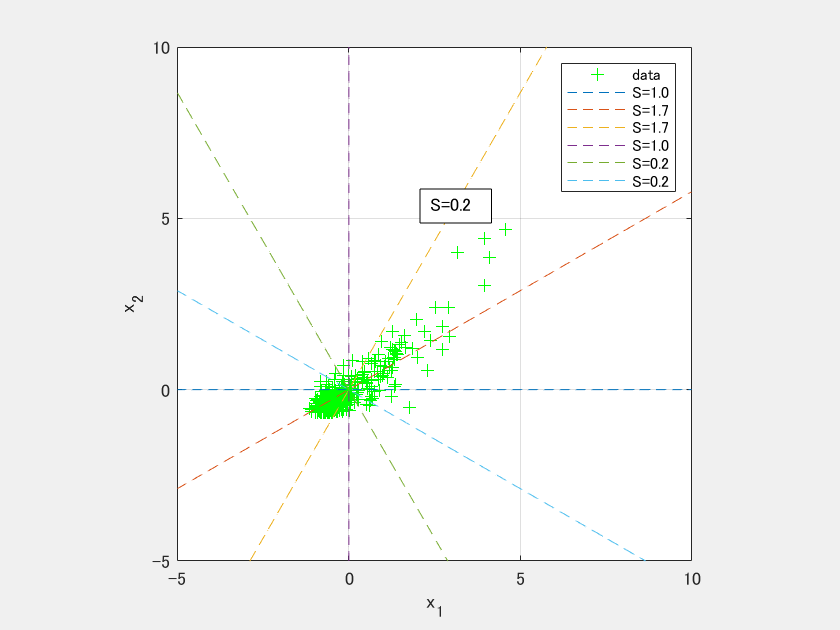

fh1=figure('Name','Fig.3-2: Variance animation','Visible','on');
plot(X(1,:),X(2,:),'g+'); hold on;
axis([-5 10 -5 10]); axis square; grid on;
xlabel('x_1'); ylabel('x_2');

slope_origin = [1 0]';
d_deg = 30;
rot_deg = 0:d_deg:180-d_deg;
legend_cell = cell(length(rot_deg)+1,1);
legend_cell{1} = 'data';
for k = 1:length(rot_deg)
    
    slope_rot = [cosd(rot_deg(k)) -sind(rot_deg(k)); sind(rot_deg(k)) cosd(rot_deg(k))]*slope_origin;
    slope_rot = slope_rot/norm(slope_rot); % normalization
    if isinf(slope_rot(2)/slope_rot(1))
        t1 = zeros(1,1000);
        t2 = linspace(-5,10,1000);
    else
        t1 = linspace(-5,10,1000);
        t2 = slope_rot(2)/slope_rot(1)*t1;
    end
    plot(t1,t2,'--');
    
    v_slope = var(slope_rot'*X,1);
    v_str = sprintf('S=%0.1f',v_slope);
    legend_cell{k+1} = v_str;
    annotation('textbox',[.5 .4 .3 .3],'String',v_str,'FitBoxToText','on','BackgroundColor','w');
    pause;
end
legend(legend_cell);

図中の小枠にそれぞれの直線に射影したときの射影ベクトルの分散を表示しました．直線の傾きが代わると分散も変化していくのがわかるかと思います．データの広がりが大きい方向では，その分散も大きくなっています．黄色と紫色の破線の間で分散$S$は最大となりそうです．

## 正射影ベクトルの長さ分散の定式化と分散共分散行列

正射影ベクトルの長さやその分散は，正射影する直線の傾きによって変化することを確認しました．ここでは，任意の単位ベクトル$u$が示す方向に射影したときの分散を定式化します．その際，分散共分散行列を定義し，その意味と性質について概説します．

### 分散の定式化

一般に，分散は平均値からのズレの大きさを表す指標で，平均値との差の二乗和として計算されます．つまり，データ点$x^{\left(i\right)}$をベクトル$u$で方向付けられる直線に射影したときの射影ベクトル$h^{\left(i\right)}$の長さを$\left\|h^{\left(i\right)} \right\|\;\left(i=1,2,\ldotp \ldotp \ldotp ,\mathrm{N}\right)$とすると，その分散$S$は


$$\mathrm{S}=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left(\left\|h^{\left(i\right)} \right\|-\bar{\left\|h\right\|} \right)}^2$$


と表されます．ここで$\bar{\left\|h\right\|} =0$でしたから，


$$\mathrm{S}=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left\|h^{\left(i\right)} \right\|}^2$$


となります．前述したように単位ベクトル$u$が示す直線への正射影ベクトルの長さは$\left\|h^{\left(i\right)} \right\|=\left(u,x^{\left(i\right)} \right)$として求められます．これを上式に代入し，変形していくと


$$\begin{array}{l}
\mathrm{S}=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left\|h^{\left(i\right)} \right\|}^2 \\
\;\;=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left(u,x^{\left(i\right)} \right)}^2 \\
\;\;=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left(u^T x^{\left(i\right)} \right)}^2 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left\lbrack \left(a,b\right)=a^T b\right\rbrack \\
\;\;=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left(u^T x^{\left(i\right)} \right)\left(u^T x^{\left(i\right)} \right)}^T \;\;\;\;\;\;\;\;\;\;\left\lbrack {\mathrm{c}}^2 =\mathrm{c}{\mathrm{c}}^T \left(={\mathrm{c}}^T \mathrm{c}=\mathrm{cc}\right)\right\rbrack \\
\;\;=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} u^T x^{\left(i\right)} {x^{\left(i\right)} }^T u\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left\lbrack {\left(e^T f\right)}^T =f^T e\right\rbrack 
\end{array}$$


となります．さらに$u$はシグマと無関係なのでシグマ記号の外に出すと，


$$\mathrm{S}=u^T \left(\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} x^{\left(i\right)} {x^{\left(i\right)} }^T \right)u$$


となります．ここで，$V=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} x^{\left(i\right)} {x^{\left(i\right)} }^T$とおくと，


$$\mathrm{S}=u^T Vu$$


となります．内積の表記を用いると，


$$\mathrm{S}=\left(u,\mathit{Vu}\right)$$


となり，任意の単位ベクトル$u$で表される直線への正射影ベクトルの長さの分散を定式化することができました．

### 分散共分散行列

上記の$V$は分散共分散行列と呼ばれます．ここでは，分散共分散行列のいくつかの特徴を紹介します．

#### 分散共分散行列のサイズ

まずは，分散共分散行列を成分で書き下してみます．


$$\begin{array}{l}
V=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} x^{\left(i\right)} {x^{\left(i\right)} }^T \\
\;\;\;=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} \left\lbrack \begin{array}{c}
{{\mathrm{x}}_1 }^{\left(i\right)} \\
{{\mathrm{x}}_2 }^{\left(i\right)} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
{{\mathrm{x}}_1 }^{\left(i\right)}  & {{\mathrm{x}}_2 }^{\left(i\right)} 
\end{array}\right\rbrack \\
\;\;\;=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} \left\lbrack \begin{array}{cc}
{\left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} \right)}^2  & {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \\
{{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)}  & {\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \right)}^2 
\end{array}\right\rbrack \\
\;\;\;=\left\lbrack \begin{array}{cc}
\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} \right)}^2  & \frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \\
\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)}  & \frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \right)}^2 
\end{array}\right\rbrack 
\end{array}$$


このように，２行２列の行列になります．一般的に，$p$個の変数を持つデータの分散共分散行列は$p\times p$の正方行列になります．三変数のデータの場合に，分散共分散行列が$3\times 3$の正方行列になるか確かめてみてください．

#### 分散共分散行列と分散

分散共分散行列の対角成分についてみると，それぞれ$\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} \right)}^2$や$\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \right)}^2$となっています．これらは，データ行列$X$の各行ごとの二乗和です．いま，データ行列$X$の各行はぞれぞれ「健康」および「芸術」の評価値です．また，それぞれの評価値は平均が$0$になるように正規化されていました．ここで，各変数の平均値をあえて${\mathrm{x}}_1 \left(=0\right)$，${\mathrm{x}}_2 \left(=0\right)$とすると，二つの対角成分はそれぞれ，  


$$\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} \right)}^2 =\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} -\bar{{\mathrm{x}}_1 } \right)}^2$$



$$\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \right)}^2 =\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} -\bar{{\mathrm{x}}_2 } \right)}^2$$


となり，各変数の分散と一致します．つまり，分散共分散行列の対角成分はデータの変数ごとの分散になります．

#### 分散共分散行列と共分散

つづいて，分散共分散行列の非対角成分についてみてみます．非対角成分はいずれも，$\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)}$となっています．ここでも，各変数の平均値をあえて${\mathrm{x}}_1 \left(=0\right)$，${\mathrm{x}}_2 \left(=0\right)$として，非対角成分を変形すると，


$$\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} =\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} \left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} -{\mathrm{x}}_1 \right)\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} -{\mathrm{x}}_2 \right)$$


となります．右辺の$\left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} -{\mathrm{x}}_1 \right)$および$\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} -{\mathrm{x}}_2 \right)$はそれぞれ，変数ごとの偏差（平均値からのズレ）を表しています．つまり，分散共分散行列の非対角成分は変数ごとの偏差を掛け合わせたものの総和です．このような値は共分散と呼ばれます．上記の式から共分散が以下のような性質を持つことがわかります．

- 一つ目の変数（${{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)}$）が平均値より大きくなれば二つ目の変数（${{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)}$）も平均値より大きくなる→共分散は正の値

- ${{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)}$が平均値より小さくなれば${{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)}$も平均値より小さくなる→共分散は正の値

- ${{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)}$が平均値より大きくなれば${{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)}$は平均値より小さくなる→共分散は負の値

- ${{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)}$が平均値より小さくなれば${{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)}$は平均値より大きくなる→共分散は負の値

このように，共分散は二つの変数の相関関係を表します．実際に，共分散を二つの変数の標準偏差で割ると，相関係数となります（以下参照）．


$$\frac{\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} \left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} -{\mathrm{x}}_1 \right)\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} -{\mathrm{x}}_2 \right)}{\sqrt{\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} -\bar{{\mathrm{x}}_1 } \right)}^2 }\sqrt{\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} -\bar{{\mathrm{x}}_2 } \right)}^2 }}$$


相関係数は，共分散が$-1$から$1$の間の値になるようにそれぞれの変数の標準偏差で割って規格化したものと言えます．

#### 多変量データの分散共分散行列

ここで，多変量データの場合に，その分散共分散行列がどのようになるか指摘しておきます．いま，多変量データが$p$個（$p>2$）の変数を持ち，$N$個の観測から成り立っているとすると，そのデータ行列$X$は，


$$X=\left\lbrack \begin{array}{ccc}
{\mathrm{x}}_1^{\left(1\right)}  & \cdots  & {\mathrm{x}}_1^{\left(\mathrm{N}\right)} \\
\vdots  & \ddots  & \vdots \\
{\mathrm{x}}_{\mathrm{p}}^{\left(1\right)}  & \cdots  & {\mathrm{x}}_{\mathrm{p}}^{\left(\mathrm{N}\right)} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
\vdots \\
x_p 
\end{array}\right\rbrack$$


と表すことができます．ここで，各変数を行に，各観測を列にしていることに注意してください．最右辺は，行ごとにベクトルにまとめて表記したものです．このとき，データ行列$X$の分散共分散行列は，

    
$$V=\left\lbrack \begin{array}{ccc}
\mathrm{V}\left(x_1 \right) & \cdots  & \mathrm{Cov}\left(x_1 ,x_p \right)\\
\vdots  & \ddots  & \vdots \\
\mathrm{Cov}\left(x_p ,x_1 \right) & \cdots  & \mathrm{V}\left(x_p \right)
\end{array}\right\rbrack$$


と表されます．このとき，$\mathrm{V}\left(x_i \right)$は$i$番目の変数の分散を表し，$\mathrm{Cov}\left(x_i ,x_j \right)$は$i$番目の変数と$j$番目の変数の共分散を表します．$\mathrm{Cov}\left(x_i ,x_j \right)=\mathrm{Cov}\left(x_j ,x_i \right)$ですので，分散共分散行列の右上の非対角成分と左下の対角成分は等しくなります．つまり，分散共分散行列は対象行列となり，


$$V^T =V$$


が成り立ちます．上付き文字の$T$は行列（またはベクトル）の転地を表します．

#### 分散共分散行列の求め方

分散共分散行列は


$$V=\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} x^{\left(i\right)} {x^{\left(i\right)} }^T$$


のように計算することができます．いま，$N$個の観測からなる二変量データのデータ行列$X$を，


$$X=\left\lbrack \begin{array}{ccc}
{\mathrm{x}}_1^{\left(1\right)}  & \cdots  & {\mathrm{x}}_1^{\left(\mathrm{N}\right)} \\
{\mathrm{x}}_2^{\left(1\right)}  & \cdots  & {\mathrm{x}}_2^{\left(\mathrm{N}\right)} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
x^{\left(1\right)}  & \cdots  & x^{\left(\mathrm{N}\right)} 
\end{array}\right\rbrack$$


とします．ここで，各変数を行に，各観測を列にしていることに注意してください．最右辺は，各列（＝観測）をベクトルとしてまとめて表記したものです．$x^{\left(i\right)}$は$i$番目の列（＝観測）を表す列ベクトルです．このとき，分散共分散行列$V$は，


$$V=\frac{1}{\mathrm{N}}XX^T$$


と表すことができます．$\mathrm{N}=329$として，実際に計算すると，

V = (1/329)*(X*X')

V =     0.9970    0.8632
    0.8632    0.9970


となります．

また，MATLABには分散共分散行列を求めるためのcov()関数が標準で組み込まれています．実際に計算すると，

V = cov(X',1)

V =     0.9970    0.8632
    0.8632    0.9970


となり，前述の結果と一致します．なお，cov()関数には，行が観測，列が変数となるデータ行列を渡さなければいけないので，転地しています．また，二つ目の入力引数を1にすることで，標本分散を計算するように指定しています（※）．

#### ※標本分散と不偏分散

分散には標本分散と不偏分散という２つの分散があります．標本分散は，


$$s=\frac{1}{\mathrm{N}}\sum_{\mathrm{i}=1}^{\mathrm{N}} {\left({\mathrm{x}}^{\left(\mathrm{i}\right)} -\bar{\mathrm{x}} \right)}^2$$


のように，偏差の二乗和を観測数$\mathrm{N}$で割ります．不偏分散は，


$$\sigma^ˆ =\frac{1}{\mathrm{N}}\sum_{\mathrm{i}=1}^{\mathrm{N}} {\left({\mathrm{x}}^{\left(\mathrm{i}\right)} -\bar{\mathrm{x}} \right)}^2$$


のように，偏差の二乗和を$\mathrm{N}-1$で割ったものです．

## 正射影ベクトルの長さの分散$\mathrm{S}$の視覚的イメージ

最後に，任意の単位ベクトルが示す方向における分散を，単位ベクトルの関数としてとらえて，立体的なグラフとして視覚的に理解できるように試みます．このイメージは本稿で解説する「分散共分散行列の固有値分解によるPCA」の核となるイメージです．

### 正射影ベクトルの長さの分散を単位ベクトルの関数として表す

上記で求めた分散共分散行列の値を$S=\left(u,\mathit{Vu}\right)$に代入してみます．


$$\mathrm{S}=\left(u,\left\lbrack \begin{array}{cc}
0\ldotp 9970 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970
\end{array}\right\rbrack u\right)$$
 

となります．これに$u=\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack$を代入してさらに変形していきます．


$$\begin{array}{l}
\mathrm{S}=\left(\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
0\ldotp 9970 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack \right)\\
\;\;\;=\left(\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\ldotp 9970{\mathrm{u}}_1 +0\ldotp 8632{\mathrm{u}}_2 \\
0\ldotp 8632{\mathrm{u}}_1 +0\ldotp 9770{\mathrm{u}}_2 
\end{array}\right\rbrack \right)\\
\;\;\;=0\ldotp 9770{\mathrm{u}}_1^2 +2\times 0\ldotp 8632{\mathrm{u}}_1 {\mathrm{u}}_2 +0\ldotp 9770{\mathrm{u}}_2^2 
\end{array}$$


これで，分散$\mathrm{S}$を$u={\left\lbrack \begin{array}{cc}
{\mathrm{u}}_1  & {\mathrm{u}}_2 
\end{array}\right\rbrack }^T$の関数として表現することができました．

### 関数$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=0\ldotp 9770{\mathrm{x}}_1^2 +2\times 0\ldotp 8632{\mathrm{x}}_1 {\mathrm{x}}_2 +0\ldotp 9770{\mathrm{x}}_2^2$のグラフ

任意の単位ベクトルと分散の関係をグラフにして視覚的に理解できるようにするために，まず，$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=0\ldotp 9770{\mathrm{x}}_1^2 +2\times 0\ldotp 8632{\mathrm{x}}_1 {\mathrm{x}}_2 +0\ldotp 9770{\mathrm{x}}_2^2$として，関数${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$のグラフを作成します．

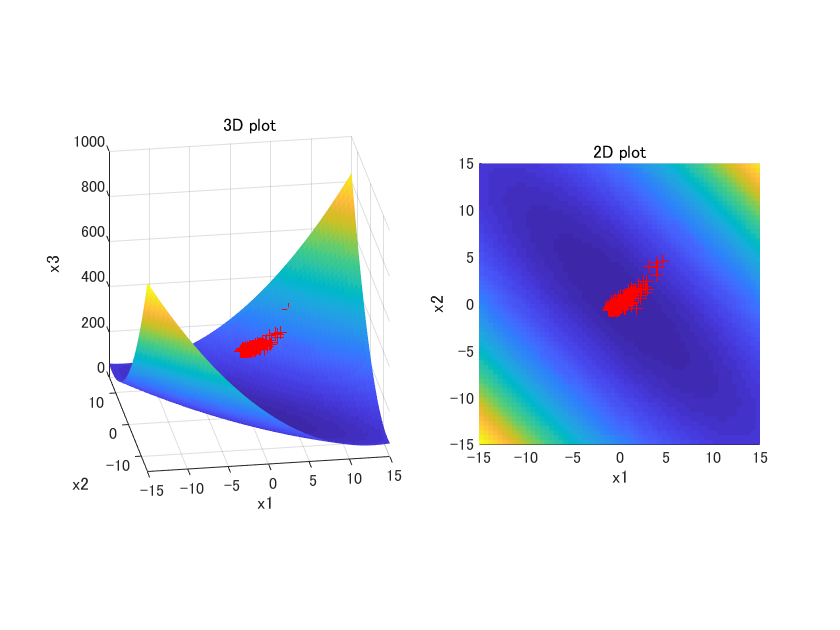

figure('Name','Fig.3-3: Visualization of S=(u,Vu)');
[x1grid,x2grid] = meshgrid(-15:0.5:15, -15:0.5:15);
% z = 0.9970x^2+ 2*0.8632xy + 0.9770y^2; % cf. [https://www.wolframalpha.com/input/?i=z+%3D+0.9970x%5E2%2B+2*0.8632xy+%2B+0.9770y%5E2]
x3 = V(1,1)*x1grid.^2 + 2*V(1,2)*x1grid.*x2grid + V(2,2)*x2grid.^2; 
subplot(1,2,1); s = surf(x1grid,x2grid,x3); view([-9 23]);
s.EdgeColor = 'none'; axis square;
title('3D plot'); xlabel('x1'); ylabel('x2'); zlabel('x3');
hold on; scatter3(X(1,:),X(2,:),ones(size(X(1,:)))*300,'r+');
axis([-15 15 -15 15 0 1000]);
subplot(1,2,2); s = surf(x1grid,x2grid,x3); view([0 90]);
s.EdgeColor = 'none'; axis square;
title('2D plot'); xlabel('x1'); ylabel('x2'); zlabel('x3');
hold on; scatter3(X(1,:),X(2,:),ones(size(X(1,:)))*200,'r+');
axis([-15 15 -15 15 0 1000]);

上図左の三次元表面プロットが${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の関係を表しています．この関数ははひしゃげたお椀のような形をしているのが見て取れます．表面プロットの色は$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の大きさに対応しており，値が大きくなると，青から黄色に変化します．$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の値は原点から離れるほど大きくなっています．さらに，$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の勾配は$\textrm{x1}$-$\mathrm{x2}$平面上の方向によって変わっています．たとえば，$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の勾配は第一象限と第三象限において大きくなっています．これはデータの分布と関係しています．比較のため，データ行列$X$を$\mathrm{x3}=300$平面上にプロットしています（赤色十字）．データの分布がもっとも広がっている方向において，$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の勾配は大きくなります．上図右は左の図を上から眺めたものです．データは第一象限と第三象限の方向に大きく広がっており，その方向において$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の勾配が大きくなっているのがわかります．これで${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の関係を視覚的に表現することができました．

### 正射影ベクトルの長さの分散のグラフ

上記のグラフは目的とするグラフではありません．ここで，$\mathrm{S}=\left(u,\mathit{Vu}\right)$におけるベクトル$u$は射影先の直線の傾きを表し，長さが$1$（$\left\|u\right\|=1$）になるように規格化された単位ベクトルであることを思い出してください．つまり，$\mathrm{S}=\left(u,\mathit{Vu}\right)$は


$$\begin{array}{l}
{\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)\\
{{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1
\end{array}$$


を満たす曲線ということになります．それぞれの関係式を実際にグラフにすると，${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$はさきほどの曲面，${{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1$は円柱になります．以下にグラフを示します．

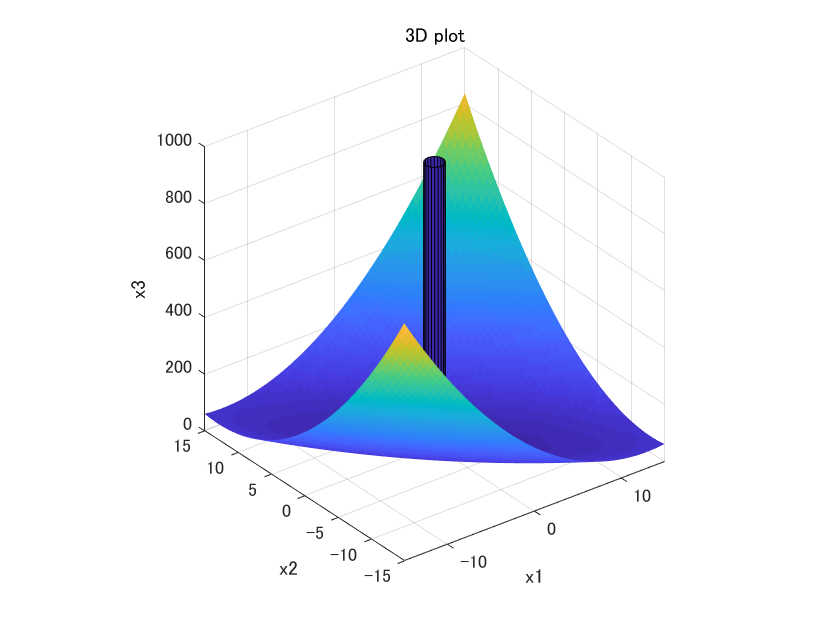

figure('Name','Fig.3-4: Visualazation of (u,Vu) with a cylinder');
[x1grid,x2grid] = meshgrid(-15:0.5:15, -15:0.5:15);
% z = 0.9970x^2+ 2*0.8632xy + 0.9770y^2; % cf. [https://www.wolframalpha.com/input/?i=z+%3D+0.9970x%5E2%2B+2*0.8632xy+%2B+0.9770y%5E2]
x3 = V(1,1)*x1grid.^2 + 2*V(1,2)*x1grid.*x2grid + V(2,2)*x2grid.^2;
s = surf(x1grid,x2grid,x3); title('3D plot');
xlabel('x1'); ylabel('x2'); zlabel('x3');
s.EdgeColor = 'none'; axis square; hold on;
[xcyl,ycyl,zcyl] = cylinder(1);
scyl = surf(xcyl, ycyl, zcyl*1000); % cylinder
axis([-15 15 -15 15 0 1000]);

この二つの曲面の交点が求めるべきグラフということになります．以下に，曲面${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$と円柱${{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1$の交点のみをグラフにします．

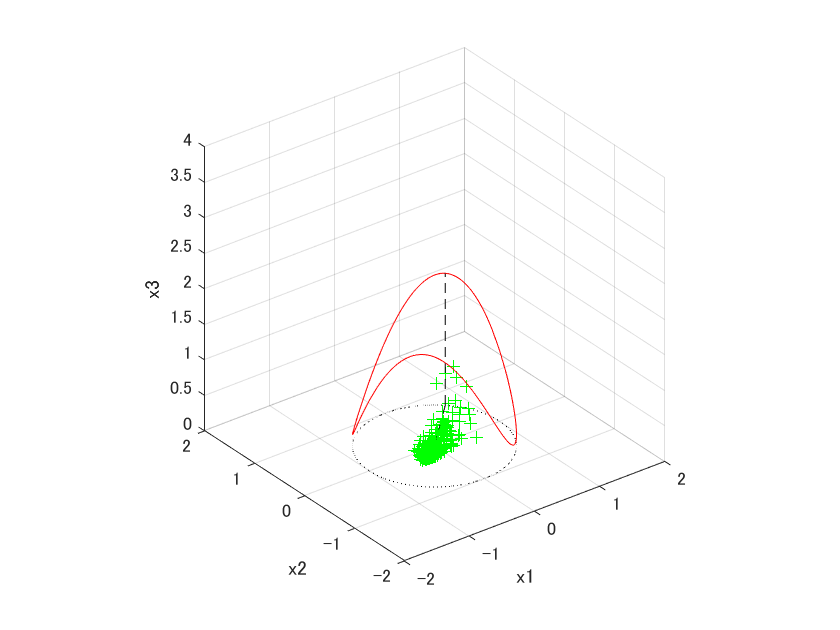

figure('Name','Fig.3-5: Visualazation of S=(u,Vu)');
xcirc = [-1:0.01:1]';
ycirc1 = sqrt(1-xcirc.^2);
ycirc2 = -sqrt(1-xcirc.^2);
for ii = 1:length(xcirc)
    zcirc1(ii) = [xcirc(ii) ycirc1(ii)]*V*[xcirc(ii) ycirc1(ii)]';
end
for ii = 1:length(xcirc)
    zcirc2(ii) = [xcirc(ii) ycirc2(ii)]*V*[xcirc(ii) ycirc2(ii)]';
end
figure('Name','Fig.3-5: S=(u,V) where (u,u)=1');
plot3(xcirc,ycirc1,zcirc1,'r-'); hold on; plot3(xcirc,ycirc2,zcirc2,'r-'); axis square;
plot3(xcirc,ycirc1,zeros(size(zcirc1)),'k:'); plot3(xcirc,ycirc2,zeros(size(zcirc2)),'k:');
xlim([-2 2]); ylim([-2 2]); zlim([0 4]); grid on;
xlabel('x1'); ylabel('x2'); zlabel('x3');
%view([-30.31 42.34]);
scatter3(X(1,:)*0.3,X(2,:)*0.3,zeros(size(X(1,:))),'g+');
% pca
[coef,score,latent] = pca(X');
arrow3([0 0 0], [coef(:,1)' 0], 'k--',0);
arrow3([coef(:,1)' 0], [coef(:,1)' latent(1)],'k--',0);

% % eigenvectors
% [Q,D] = eig(X*X'/100); % l.32
% [~,ind] = sort(diag(D),'descend'); % l.33
% D = D(ind,ind); Q = Q(:,ind); % l.34
% arrow3([0 0 0], [Q(1,1) Q(2,1) 0],'k-'); text(Q(1,1),Q(2,1),0,'u_{max}','VerticalAlignment','top');
% arrow3([Q(1,1) Q(2,1) 0], [Q(1,1) Q(2,1) D(1,1)], 'k--', 0); text(Q(1,1),Q(2,1),D(1,1),'S_{max}','VerticalAlignment','bottom');
% arrow3([0 0 0], [Q(1,2) Q(2,2) 0],'k-'); text(Q(1,2),Q(2,2),0,'u_{min}','VerticalAlignment','top');
% arrow3([Q(1,2) Q(2,2) 0], [Q(1,2) Q(2,2) D(2,2)], 'k--', 0); text(Q(1,2),Q(2,2),D(2,2),'S_{min}','VerticalAlignment','bottom');

赤い曲線が二つの関数の交点を表します．鞍のような形状をしています．黒い点線で，$\mathrm{x1}$-$\mathrm{x2}$平面上に${{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1$で表される単位円を書いています．緑色の十字はデータを表します．曲線を見やすくするために，原点付近を拡大しており，データの一部は表示されていません．曲線とデータの分布を見比べると，データがもっとも広がっている方向において，曲線が最大値に達しているように見えます（黒破線）．

## これまでのまとめ

本章では，任意の方向における分散の定式化し，できるだけ幾何学的に理解できるように試みました．

- まず，射影ベクトルを導入しました．その射影ベクトルの長さは，任意の単位ベクトル$u$とデータベクトル$x^{\left(i\right)}$との内積$\left(u,x^{\left(i\right)} \right)$として表されます．

- つぎに，射影ベクトルの長さの分散を導入しました．また，データの分散共分散行列を定義しました．分散共分散行列を$V$とすると，長さの分散は$\mathrm{S}=\left(u,\mathit{Vu}\right)$として表されます．ただし，$\left\|u\right\|=1$です．

- 最後に，正射影ベクトルの長さの分散$\mathrm{S}=\left(u,\textrm{Vu}\right)$の視覚的なイメージを紹介しました．$\mathrm{S}=\left(u,\textrm{Vu}\right)$は曲面$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,V\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)$と円柱${{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1$の交点として表現することができました．この曲線はデータの分布と密接に関係しており，データがもっとも広がっている方向において曲線が最大値に達し，データの広がりが最も小さい方向において曲線は最小になるという関係があります．

正射影ベクトルの長さの分散$\mathrm{S}=\left(u,\textrm{Vu}\right)$とデータの分布との関係がPCAの核心部です．前章や本章で指摘したように，二変量データを含む多変量データの分散は，どの方向の分散を計算するかによってその値が変わります．したがって，PCAで次元圧縮を行う際にまず重要なことは，データの分散を最大限に表す方向（主軸）はどの方向かということです．この方向はデータの分布に依存します．本章の最後で確認したように，データの分布がもっとも広がっている方向が，正射影ベクトルの長さの分散が最大となる方向です．

さて，本章の冒頭で「データの分散が最大限に含まれる方向（主軸）を探す」という課題を解くうえで基本的な考え方を関数の最大値を求める方法になぞらえました．つまり，そのステップを

- 任意の方向における分散を定式化する

- 分散が最大になるときの方向（主軸）を見つける

と分けて示しました．そして，本章で一つ目の定式化を解説しました．次章では．定式化を利用して，分散が最大となる方向と分散共分散行列$V$の固有値分解との関係をみていきます．